k=398600; 
dt=10; % time step interval
r=6678; % radius
w=sqrt(k/(r^3)); % angular velocity

A=[0,1,0,0;3*w^2,0,0,2*r*w;0,0,0,1;0,-2*w/r,0,0] 

A =          0    1.0000         0         0
    0.0000         0         0   15.4517
         0         0         0    1.0000
         0   -0.0000         0         0


B=[0,0;1,0;0,0;0,1/r]

B =          0         0
    1.0000         0
         0         0
         0    0.0001


C= [1,0,0,0;0,0,1,0]

C =      1     0     0     0
     0     0     1     0


D=zeros(2)

D =      0     0
     0     0


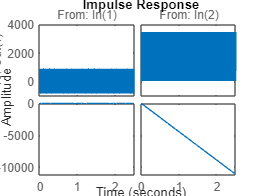


C1=zeros(2,4); % zero out C for DT translation
AB=[A,B;C1,D]; 
FG=expm(AB*dt); % find translation to DT

Ahat=FG(1:4,1:4); % DT A matrix
Bhat = FG(1:4,5:6); % DT B matrix

sys=ss(A,B,C,[]); % convert system to state space object
syshat=ss(Ahat,Bhat,C,D,dt); % DT system converted to state space object
impulse(sys)

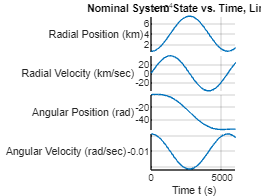

t = 0:10:6000; % time vector (s)
x = zeros(length(t),2); % inputs

x0=[r;0;0;w]; % Initial conditions
[z,tOut,xout]=lsim(syshat,x,t,x0); % Initial conditions CT system

% x0_2=[r+10;-.5;0;.0012+2.5e-5]; % Initial conditions with perturbation
% [z2,tOut_2,xout_2]=lsim(sys,x,t,x0_2); % total state changes for CT system

x0_4=[10,-.5,0,2.5e-5]; % Initial conditions for perturbations only
[z4,tOut_4,xout_4]=lsim(syshat,x,t,x0_4); % state changes due to perturbations

figure;
s=stackedplot(tOut, xout);
xlabel('Time t (s)');
s.DisplayLabels={'Radial Position (km)', 'Radial Velocity (km/sec)', 'Angular Position (rad)', 'Angular Velocity (rad/sec)'};
ax = findobj(s.NodeChildren, 'Type','Axes');
set([ax.YLabel],'Rotation',90,'HorizontalAlignment', 'Center', 'VerticalAlignment', 'Bottom')
title('Nominal System State vs. Time, Linearized');
grid on;

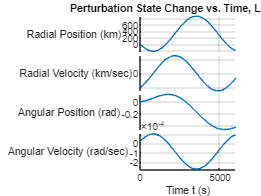


% figure;
% s=stackedplot(tOut_2, xout_2);
% xlabel('Time t (s)');
% s.DisplayLabels={'Radial Position (km)', 'Radial Velocity (km/sec)', 'Angular Position (rad)', 'Angular Velocity (rad/sec)'};
% ax = findobj(s.NodeChildren, 'Type','Axes');
% set([ax.YLabel],'Rotation',90,'HorizontalAlignment', 'Center', 'VerticalAlignment', 'Bottom')
% title('Total Perturbation State Change vs. Time, Linearized');
% grid on;
% 

figure;
s=stackedplot(tOut_4, xout_4);
xlabel('Time t (s)');
s.DisplayLabels={'Radial Position (km)', 'Radial Velocity (km/sec)', 'Angular Position (rad)', 'Angular Velocity (rad/sec)'};
ax = findobj(s.NodeChildren, 'Type','Axes');
set([ax.YLabel],'Rotation',90,'HorizontalAlignment', 'Center', 'VerticalAlignment', 'Bottom')
title('Perturbation State Change vs. Time, Linearized');
grid on;

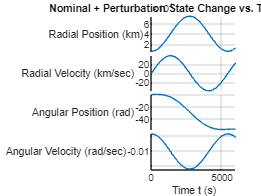


xtotlin = xout_4+xout; % add nominal response to perturbation response

figure;
s=stackedplot(tOut_4, xtotlin);
xlabel('Time t (s)');
s.DisplayLabels={'Radial Position (km)', 'Radial Velocity (km/sec)', 'Angular Position (rad)', 'Angular Velocity (rad/sec)'};
ax = findobj(s.NodeChildren, 'Type','Axes');
set([ax.YLabel],'Rotation',90,'HorizontalAlignment', 'Center', 'VerticalAlignment', 'Bottom')
title('Nominal + Perturbation State Change vs. Time, Linearized');
grid on;


% Part B
k=398600

k = 398600

dt=10

dt = 10

r=6678

r = 6678

w=sqrt(k/(r^3))

w = 0.0012


x0=[r+10;-.5;0;w+2.5e-5]; % perturbation initial conditions

tspan = 0:10:6000 % sample every 10 seconds

tspan =      0    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200   210   220   230   240   250   260   270   280   290   300   310   320   330   340   350   360   370   380   390   400   410   420   430   440   450   460   470   480   490


opts = odeset('RelTol',1e-32,'AbsTol',1e-32);
[t,y] = ode45(@(t,y) myfunc(t,y,k), tspan, x0, opts);

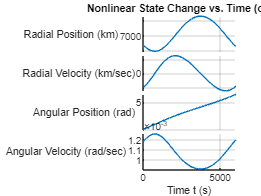


figure;
s=stackedplot(t, y);
xlabel('Time t (s)');
s.DisplayLabels={'Radial Position (km)', 'Radial Velocity (km/sec)', 'Angular Position (rad)', 'Angular Velocity (rad/sec)'};
ax = findobj(s.NodeChildren, 'Type','Axes');
set([ax.YLabel],'Rotation',90,'HorizontalAlignment', 'Center', 'VerticalAlignment', 'Bottom')
title('Nonlinear State Change vs. Time (ode45)');
grid on;

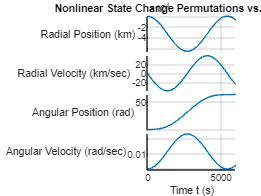


xpermnl = y-xout;  %subtract NL total state change from nominal state to get permutations

figure;
s=stackedplot(t, xpermnl);
xlabel('Time t (s)');
s.DisplayLabels={'Radial Position (km)', 'Radial Velocity (km/sec)', 'Angular Position (rad)', 'Angular Velocity (rad/sec)'};
ax = findobj(s.NodeChildren, 'Type','Axes');
set([ax.YLabel],'Rotation',90,'HorizontalAlignment', 'Center', 'VerticalAlignment', 'Bottom')
title('Nonlinear State Change Permutations vs. Time (ode45)');
grid on;

function dy=myfunc(t,y,a)
    dy=zeros(4,1);

    dy(1)=y(2);
    dy(2)=y(1).*(y(4)^2)-(a./(y(1)^2));
    dy(3)=y(4);
    dy(4)=(-2.*y(2).*(y(4))./y(1));
end


